# Bulk Water RDF Comparison

input files

rdf_tip3p = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\rdf\bulk water\tip3p.rdf";
rdf_spc = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\rdf\bulk water\spc.rdf";
rdf_tip4p = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\rdf\bulk water\tip4p.rdf";
rdf_tip5p = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\rdf\bulk water\tip5p.rdf";


Timestep of Simulation

timestep = 1/1000; %always real

Number of Steps

numSteps = 100000;
maxTime = timestep*numSteps;

steps per rdf print & numBins

perStep_rdf = 1000;
maxSteps_rdf = numSteps/perStep_rdf;
numBins = 1000;



[time_tip3p,Bins_tip3p,rdf_ave_oh_tip3p,rdf_ave_hh_tip3p,rdf_ave_oo_tip3p] = h2o_rdf(rdf_tip3p,maxSteps_rdf,numBins);
[time_spc,Bins_spc,rdf_ave_oh_spc,rdf_ave_hh_spc,rdf_ave_oo_spc] = h2o_rdf(rdf_spc,maxSteps_rdf,numBins);
[time_tip4p,Bins_tip4p,rdf_ave_oh_tip4p,rdf_ave_hh_tip4p,rdf_ave_oo_tip4p] = h2o_rdf(rdf_tip4p,maxSteps_rdf,numBins);
[time_tip5p,Bins_tip5p,rdf_ave_oh_tip5p,rdf_ave_hh_tip5p,rdf_ave_oo_tip5p] = h2o_rdf(rdf_tip5p,maxSteps_rdf,numBins);

[soper_HH,soper_OH,soper_OO] = read_Soper("Logs\rdf\bulk water\soper_HH","Logs\rdf\bulk water\soper_OH","Logs\rdf\bulk water\soper_OO");

### Plot RDF at timestep

Plot up to 3 rdf plots on the same plot. timeStep# is in units of rdf prints.

Use 0 for don't plot. Messes up the legend if the 0 is not at the end. 

timeStep1 =100;
filter_strength = 10;


legend_text = ["SPC" "TIP3P" "TIP4P" "TIP5P" "Experimental"];

warning('off','matlab:legend:IgnoringExtraEntries'); %Turn off warning when -1 is used


rdfOH_tip3p = Bins_tip3p(:,3,timeStep1);
rdf_ave_OH_tip3p = move_avg(rdfOH_tip3p,10,true);
rdfHH_tip3p = Bins_tip3p(:,5,timeStep1);
rdf_ave_HH_tip3p = move_avg(rdfHH_tip3p,10,true);
rdfOO_tip3p = Bins_tip3p(:,7,timeStep1);
rdf_ave_OO_tip3p = move_avg(rdfOO_tip3p,10,true);

rdfOH_tip4p = Bins_tip4p(:,3,timeStep1);
rdf_ave_OH_tip4p = move_avg(rdfOH_tip4p,10,true);
rdfHH_tip4p = Bins_tip4p(:,5,timeStep1);
rdf_ave_HH_tip4p = move_avg(rdfHH_tip4p,10,true);
rdfOO_tip4p = Bins_tip4p(:,7,timeStep1);
rdf_ave_OO_tip4p = move_avg(rdfOO_tip4p,10,true);

rdfOH_tip5p = Bins_tip5p(:,3,timeStep1);
rdf_ave_OH_tip5p = move_avg(rdfOH_tip5p,10,true);
rdfHH_tip5p = Bins_tip5p(:,5,timeStep1);
rdf_ave_HH_tip5p = move_avg(rdfHH_tip5p,10,true);
rdfOO_tip5p = Bins_tip5p(:,7,timeStep1);
rdf_ave_OO_tip5p = move_avg(rdfOO_tip5p,10,true);

rdfOH_spc = Bins_spc(:,3,timeStep1);
rdf_ave_OH_spc = move_avg(rdfOH_spc,10,true);
rdfHH_spc = Bins_spc(:,5,timeStep1);
rdf_ave_HH_spc = move_avg(rdfHH_spc,10,true);
rdfOO_spc = Bins_spc(:,7,timeStep1);
rdf_ave_OO_spc = move_avg(rdfOO_spc,10,true);

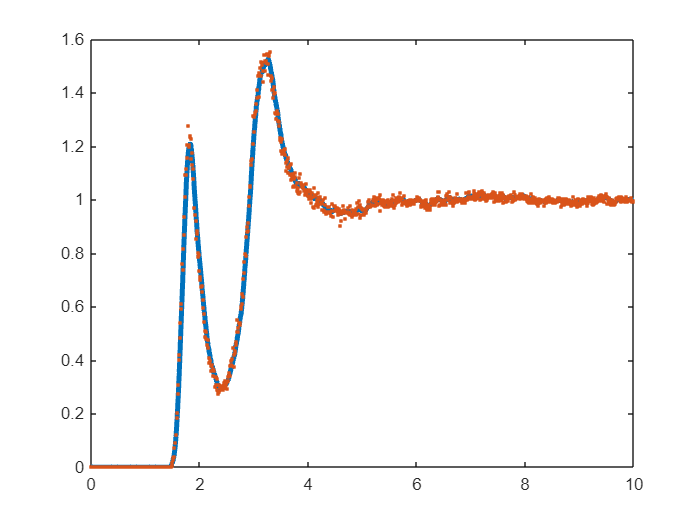


%test filtering
figure
plot(Bins_tip5p(:,2,1),rdf_ave_OH_tip5p,LineWidth=3);
hold on;
plot(Bins_tip5p(:,2,1),rdfOH_tip5p,'.');
hold off;

#### Filtered RDF Plots

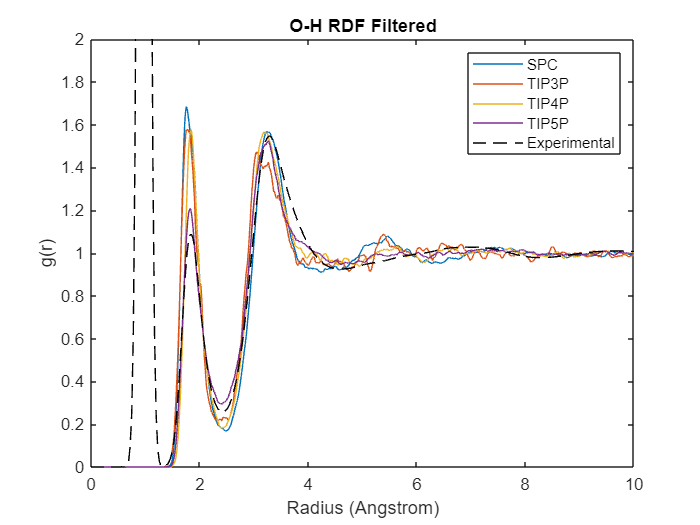

figure


plot(Bins_spc(:,2,1),rdf_ave_OH_spc);
hold on;
plot(Bins_tip3p(:,2,1),rdf_ave_OH_tip3p);
plot(Bins_tip4p(:,2,1),rdf_ave_OH_tip4p);
plot(Bins_tip5p(:,2,1),rdf_ave_OH_tip5p);
plot(soper_OH.r,soper_OH.gr,'k--');

hold off;
title("O-H RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
xlim([0 10]);
ylim([0 2]);
legend(legend_text);

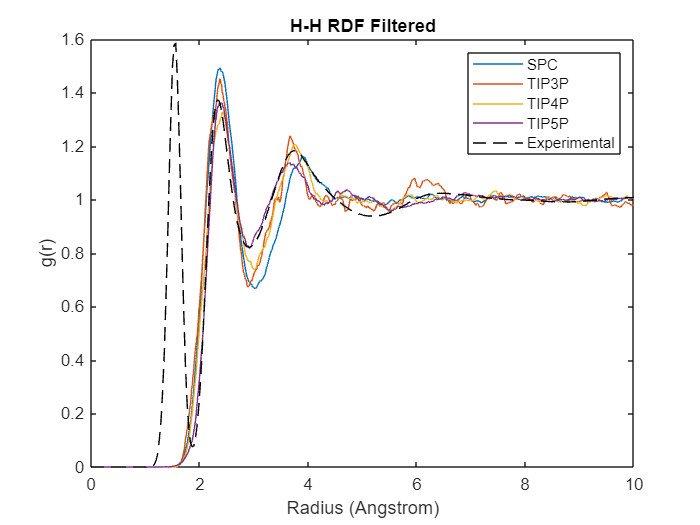


figure
plot(Bins_spc(:,2,1),rdf_ave_HH_spc);
hold on;
plot(Bins_tip3p(:,2,1),rdf_ave_HH_tip3p);
plot(Bins_tip4p(:,2,1),rdf_ave_HH_tip4p);
plot(Bins_tip5p(:,2,1),rdf_ave_HH_tip5p);
plot(soper_HH.r,soper_HH.gr,'k--');
hold off;
title("H-H RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
xlim([0 10]);
legend(legend_text);

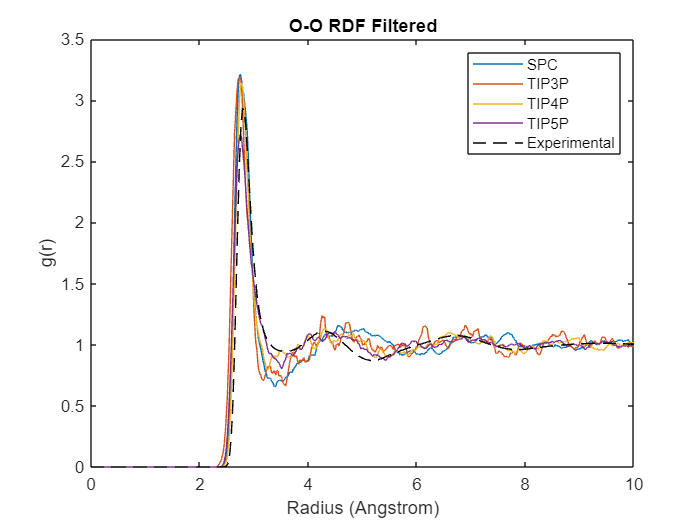


figure;
plot(Bins_spc(:,2,1),rdf_ave_OO_spc);
hold on;
plot(Bins_tip3p(:,2,1),rdf_ave_OO_tip3p);
plot(Bins_tip4p(:,2,1),rdf_ave_OO_tip4p);
plot(Bins_tip5p(:,2,1),rdf_ave_OO_tip5p);
plot(soper_OO.r,soper_OO.gr,'k--');
hold off;
title("O-O RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
xlim([0 10]);
legend(legend_text);